# **drawRect**

# **fillRect**

Draw or fill rectangle.

## Description

## Syntax

drawRect(wd,ht,xr,yr)

drawRect(wd,ht,xr,yr,rot)

drawRect(__,'-pos',ip)

drawRect(__,'-v',v1,v2)

drawRect(__,LineSpec)

p = drawRect(__)

fillRect(c,__)

### Description

drawRect(wd,ht,xr,yr) draw rectangle with reference point at position 1.

drawRect(wd,ht,xr,yr,rot) draw rectangle rotated by given angle about reference point. 

drawRect(__,'-pos',ip) draw rectangle with reference point at position ip:1,...,9, (default is 1)  (see Example 2)

drawRect(__,'-v',v1,v2) draw part of rectangle from vertex number v1 to vertex number v2 in CCLW direction. v2 is not neccesery > v1. 

drawRect(_,LineSpec)  sets the line style, marker symbol, and color.

p = drawRect(__) returns structure with fields contain x-value and y-value for the rectangle.

### Method

For calculation of the coordinates  the function use **evalRect( xr,yr,wd,ht,rot,ip,v1,v2)  **which returns coordinates *x *and *y *of the vertices v1 to v2 in CCW direction. If v1=v2 the rectangle is closed. For usage of **evalRect **see Example 1.

The curve is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**c **- fill color

**wd       **- width

**ht       **- height

**xr, yr   **- reference point 

### **Optional Input Arguments**

**rot **- rotation angle about the reference point  in degrees

**'-pos',ip **- position of reference point:1,...,9 (default is 1) (see Example 2)

** '-v',v1,v2**   -- start and end vertices in CCLW direction, 1<=v1,v2 <= 4. It is not neccesary that v1 < v2 (see Example 2)

### Optional Name-Value Pair Input Arguments

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with the fields

- p.xk - coordinates of 9 characteristic points

- p.yk

- p.color - line color

## Examples

### Example 1

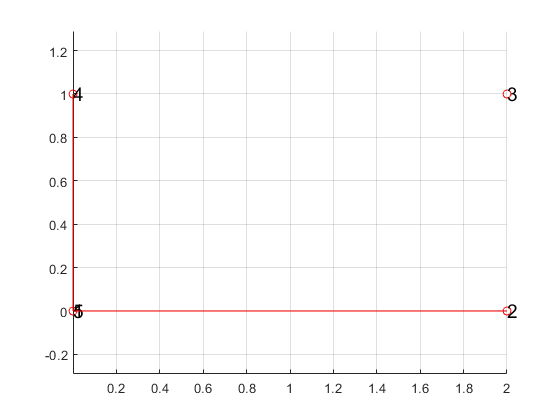

figure
hold on
axis equal
% Data
n = 5;
r = 1;
% close polygon
[xv,yv] = evalRect( 2, 1, 0, 0, 0, 1, 1, 1);
% plotvertices
scatter(xv,yv,'r')
for k = 1:n
    text(xv(k),yv(k),num2str(k),'FontSize',14)
end
% polyline between two vertices
v1 = 4;
v2 = 2;
[xv,yv] = evalRect( 2, 1, 0, 0, 0, 1, v1, v2);
% plot  polyline
plot(xv,yv,'r')
grid on

#### **Example 2**

figure
axis equal
hold on
% coordinates of polygon vertices
nv = 12; % number of vertices
% plot definiting polygon
p=drawRect(2,1,0,0,'r:')

p = struct with fields:
       xk: [9×1 double]
       yk: [9×1 double]
    color: [1 0 0]


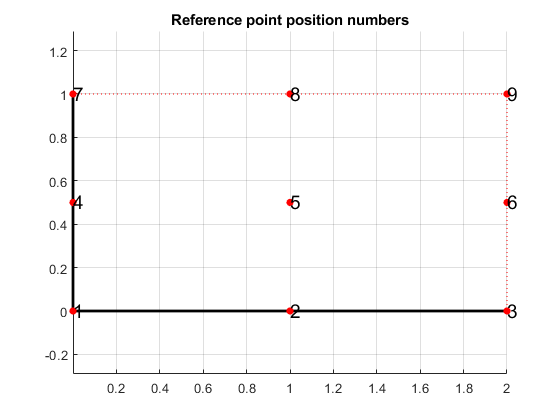

% Polyline between vertex 4 and 3
drawRect(2,1,0,0,'-v',4,2,'k','LineWidth',2);
%plot(x,y,'k','LineWidth',2)
% plot referebnce points
scatter(p.xk,p.yk,30,'r','filled')
for k = 1:9
    text(p.xk(k),p.yk(k),num2str(k),'FontSize',14)
end
title('Reference point position numbers')
grid on

#### **Example 3**

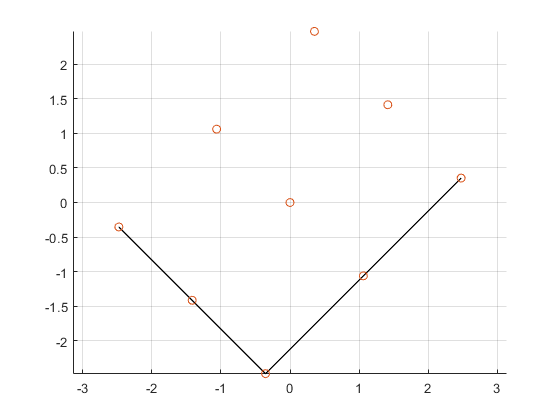

figure
axis equal
hold on
p=drawRect(4,3,0,0,45,'-v',4,2,'-pos',5);
scatter(p.xk,p.yk)
grid on

### Example 4

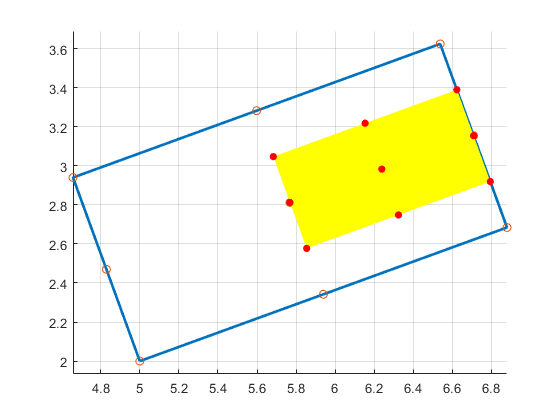

figure
axis equal
hold on
r1=drawRect(2,1,5,2,20,'LineWidth',2);
scatter(r1.xk,r1.yk)
r2=fillRect('y',1,0.5,r1.xk(5),r1.yk(5),20,'-pos',4);
scatter(r2.xk,r2.yk,30,'r','filled')
grid on

## See also

## References